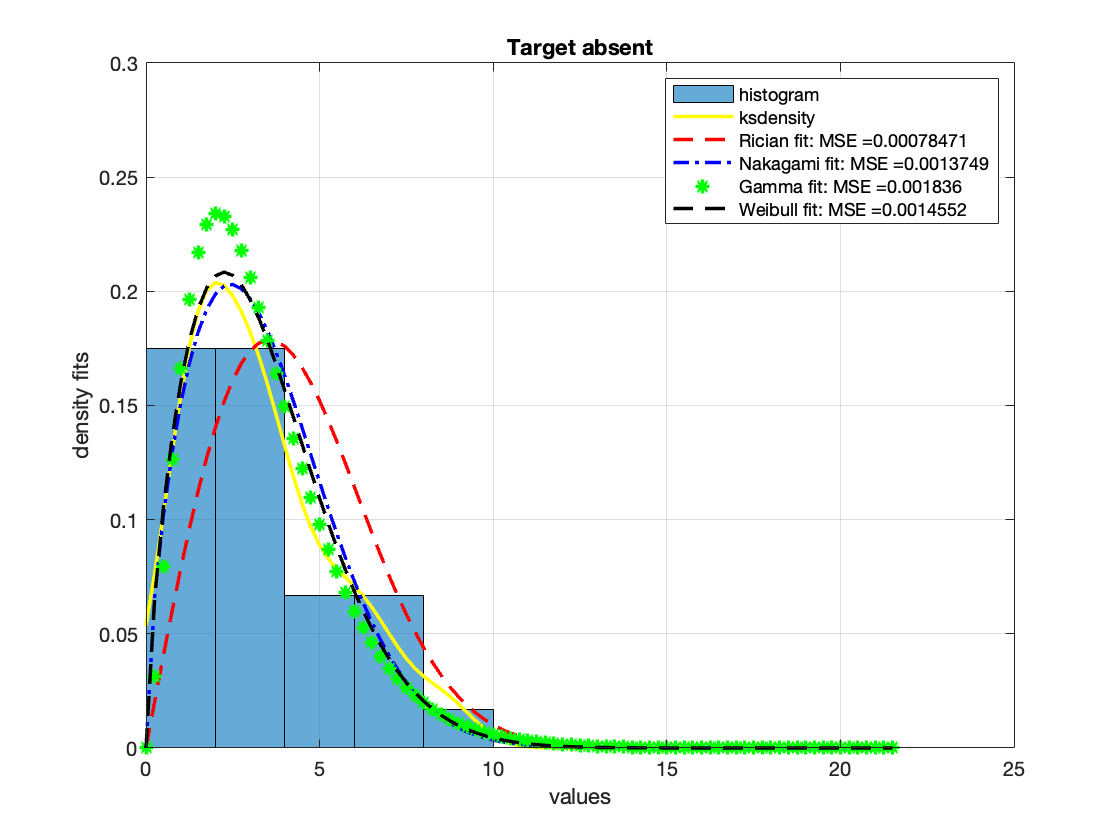

clear;
close all; clc
[status,sheets] = xlsfinfo('Douglas-HW');

% the command to read the data
A=readmatrix('Douglas-HW.xls','Sheet',1); % read the first sheet
x=A(1:60);% get the first 60 rows of 1st column
y=A(61:110); % get the next 50 of 1st column
A=A(:);
y=y(~isnan(y)); % suppress the NaN
histogram(x, 'normalization', 'pdf');
hold on
grid on 
%
xlim([0,25])
ylim([0,0.3])
xx=0:0.25:1.2*max(A);% get the x-coordinates to get the ksdensity
fx1=ksdensity(x,xx);
plot(xx,fx1,'-y','linewidth',1.75)
R=fitdist((x+1),'Rician');
G=fitdist(x,'gamma');
W=fitdist(x,'weibull');
sigma=R.sigma;
N= fitdist(x,'nakagami');
mu=N.mu;
omega=N.omega;
%xi = 0:0.5:25;
xi=0:0.25:1.2*max(A);
f_r=pdf(R,xi);
f_n=pdf('nakagami',xi,mu,omega);
f_g=pdf('gamma',xi,G.a,G.b);
f_w=pdf('weibull',xi,W.a,W.b);
[fx1]=ksdensity(A,xi);
plot(xi,f_r,'r--',xi,f_n,'b-.',xi,f_g,'g*',xi,f_w,'k--','linewidth',1.7)
LN=length(xi);
MSERic1=sum((fx1-f_r).^2)/LN;
MSENaka=sum((fx1-f_n).^2)/LN;
MSEGamma=sum((fx1-f_g).^2)/LN;
MSEWeibull=sum((fx1-f_w).^2)/LN;
xlabel('values'),ylabel('density fits')
legend('histogram','ksdensity',['Rician fit: MSE =',num2str(MSERic1)],['Nakagami fit: MSE =',num2str(MSENaka)],['Gamma fit: MSE =',num2str(MSEGamma)],['Weibull fit: MSE =',num2str(MSEWeibull)])
title("Target absent")

[h,p,st] = chi2gof(f_r)

h = 1

p = 3.8575e-07

st = struct with fields:
    chi2stat: 37.9523
          df: 5
       edges: [4.9407e-324 0.0179 0.0357 0.0536 0.0715 0.0893 0.1072 0.1251 0.1787]
           O: [50 5 4 3 3 3 3 16]
           E: [28.5430 9.3592 9.7956 9.4671 8.4488 6.9625 5.2982 9.1254]


[h,p,st] = chi2gof(f_n)

h = 1

p = 1.0047e-08

st = struct with fields:
    chi2stat: 43.0617
          df: 4
       edges: [4.9407e-324 0.0203 0.0406 0.0609 0.0812 0.1015 0.1218 0.2030]
           O: [56 4 2 3 2 3 17]
           E: [31.0341 9.8483 10.0660 9.4547 8.1607 6.4729 11.9634]


[h,p,st] = chi2gof(f_g)

h = 1

p = 1.0010e-07

st = struct with fields:
    chi2stat: 38.2375
          df: 4
       edges: [4.9407e-324 0.0234 0.0468 0.0702 0.0936 0.1170 0.1404 0.2340]
           O: [57 6 3 3 2 3 13]
           E: [32.9819 10.9114 10.8723 9.7926 7.9727 5.8674 8.6017]


[h,p,st] = chi2gof(f_w)

h = 1

p = 2.5131e-08

st = struct with fields:
    chi2stat: 41.1410
          df: 4
       edges: [4.9407e-324 0.0208 0.0417 0.0625 0.0834 0.1042 0.1251 0.2084]
           O: [56 4 3 3 2 3 16]
           E: [31.3532 10.0751 10.2545 9.5581 8.1586 6.3775 11.2229]


pees1 = [3.8575e-07, 1.0047e-08,1.0010e-07,2.5131e-08] 

pees1 = 	1.0e+-6 *

    0.3858    0.0100    0.1001    0.0251


bestfit1 = min(pees1)

bestfit1 = 1.0047e-08

fprintf("Nakagami is best fit")

Nakagami is best fit

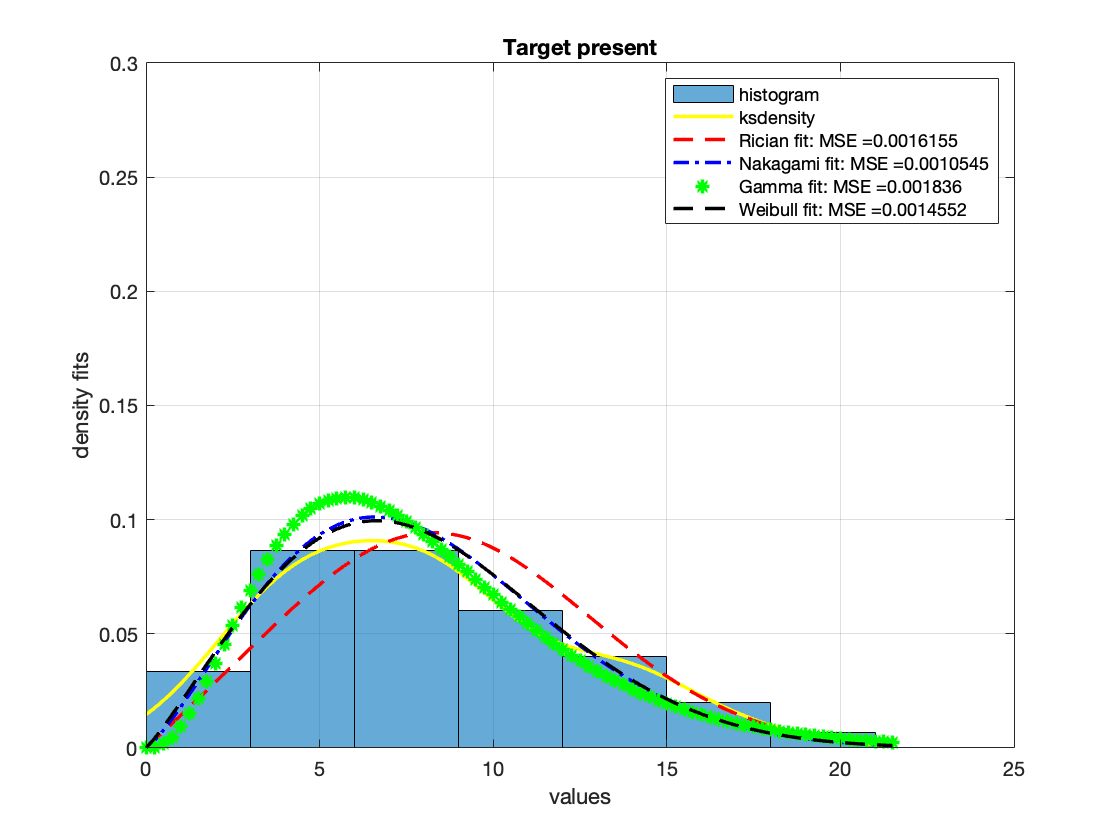



figure, histogram(y, 'normalization', 'pdf');
hold on
grid on 
title("Target present")
xlim([0,25])
ylim([0,0.3])
xx=0:0.25:1.2*max(A);% get the x-coordinates to get the ksdensity
fy1=ksdensity(y,xx);
plot(xx,fy1,'-y','linewidth',1.75)
R1=fitdist((y+1),'Rician');
G1=fitdist(y,'gamma');
W1=fitdist(y,'weibull');
sigma1=R1.sigma;
N1= fitdist(y,'nakagami');
mu1=N1.mu;
omega1=N1.omega;
%xi = 0:0.5:25;
yi=0:0.25:1.2*max(A);
f_r1=pdf(R1,yi);
f_n1=pdf('nakagami',yi,mu1,omega1);
f_g1=pdf('gamma',yi,G1.a,G1.b);
f_w1=pdf('weibull',yi,W1.a,W1.b);
[fy1]=ksdensity(A,yi);
plot(yi,f_r1,'r--',yi,f_n1,'b-.',yi,f_g1,'g*',yi,f_w1,'k--','linewidth',1.7)
LN1=length(yi);
MSERic11=sum((fy1-f_r1).^2)/LN1;
MSENaka1=sum((fy1-f_n1).^2)/LN1;
MSEGamma1=sum((fy1-f_g1).^2)/LN1;
MSEWeibull1=sum((fy1-f_w1).^2)/LN1;
xlabel('values'),ylabel('density fits')
legend('histogram','ksdensity',['Rician fit: MSE =',num2str(MSERic11)],['Nakagami fit: MSE =',num2str(MSENaka1)],['Gamma fit: MSE =',num2str(MSEGamma)],['Weibull fit: MSE =',num2str(MSEWeibull)])

[h,p,st] = chi2gof(f_r1)

h = 1

p = 0.0290

st = struct with fields:
    chi2stat: 15.6070
          df: 7
       edges: [4.9407e-324 0.0094 0.0189 0.0283 0.0377 0.0472 0.0566 0.0660 0.0755 0.0849 0.0943]
           O: [17 10 6 7 5 6 6 6 7 17]
           E: [11.6123 6.2483 7.9016 9.2061 9.8820 9.7729 8.9045 7.4749 5.7811 10.2162]


[h,p,st] = chi2gof(f_n1)

h = 1

p = 0.0169

st = struct with fields:
    chi2stat: 17.0746
          df: 7
       edges: [4.9407e-324 0.0101 0.0202 0.0304 0.0405 0.0506 0.0607 0.0708 0.0809 0.0911 0.1012]
           O: [22 9 7 5 5 6 5 6 7 15]
           E: [13.9010 6.7738 8.2703 9.3332 9.7357 9.3871 8.3660 6.8918 5.2477 9.0932]


[h,p,st] = chi2gof(f_g1)

h = 1

p = 0.0050

st = struct with fields:
    chi2stat: 18.5350
          df: 6
       edges: [4.9407e-324 0.0110 0.0219 0.0329 0.0439 0.0549 0.0658 0.0768 0.0878 0.1097]
           O: [24 11 7 6 6 4 5 5 19]
           E: [15.7137 7.4494 8.9099 9.8095 9.9416 9.2745 7.9644 6.2958 11.6412]


[h,p,st] = chi2gof(f_w1)

h = 1

p = 0.0191

st = struct with fields:
    chi2stat: 16.7486
          df: 7
       edges: [4.9407e-324 0.0100 0.0199 0.0299 0.0398 0.0498 0.0597 0.0697 0.0796 0.0896 0.0995]
           O: [21 9 7 5 6 5 5 6 8 15]
           E: [13.4809 6.6493 8.1627 9.2640 9.7201 9.4285 8.4552 7.0099 5.3728 9.4565]


pees = [0.0290, 0.0169, 0.0050, 0.0191]

pees =     0.0290    0.0169    0.0050    0.0191


bestfit = min(pees)

bestfit = 0.0050

fprintf("Gamma is best fit")

Gamma is best fit